# Multipath Fading Channel

This example shows how to use Rayleigh multipath fading channel System objects and their built-in visualization to model a fading channel. 

# Initialization

The following variables control both the Rayleigh and Rician channel objects. By default, the channel is modeled as four fading paths, each representing a cluster of multipath components received at around the same delay.

sampleRate500kHz = 500e3; % Sample rate of 500K Hz, Ts=2 us
sampleRate20kHz  = 20e3; % Sample rate of 20K Hz, Ts=50 us
maxDopplerShift  = 200; % Maximum Doppler shift of diffuse components (Hz)
delayVector = (0:5:15)*1e-6; % Discrete delays of four-path channel (s)
gainVector  = [0 -3 -6 -9]; % Average path gains (dB)

# Creating Channel System Objects

With the parameters specified above, we can now create the [`comm.RayleighChannel`](docid:comm_ref#btzwroy-1) System objects. We configure the objects to use their self-contained random stream with a specified seed for path gain generation.

% Configure a Rayleigh channel object
rayChan = comm.RayleighChannel( ...
    'SampleRate',sampleRate500kHz, ...
    'PathDelays',delayVector, ...
    'AveragePathGains',gainVector, ...
    'MaximumDopplerShift',maxDopplerShift, ...
    'RandomStream','mt19937ar with seed', ...
    'Seed',10, ...
    'PathGainsOutputPort',true);


# Modulation and Channel Filtering

Create a [`comm.QPSKModulator`](docid:comm_ref#bsnfizy_6) System object to modulate the channel data, which has been generated using the [randi](docid:matlab_ref#buf2csg) function. In the code here a 'frame' refers to a vector of information bits. A phase offset of pi/4 is used for this example.

qpskMod = comm.QPSKModulator('BitInput',true,'PhaseOffset',pi/4);

% Number of bits transmitted per frame is set to be 1000. For QPSK
% modulation, this corresponds to 500 symbols per frame.
bitsPerFrame = 1000;
msg = randi([0 1],bitsPerFrame,1);

% Modulate data for transmission over channel
modSignal = qpskMod(msg);

% Apply Rayleigh or Rician channel object on the modulated data
rayChan(modSignal);


# Visualization

The fading channel System objects have built-in visualization to show the channel impulse response, frequency response, or Doppler spectrum when the object runs. To invoke it, set the `Visualization` property to the desired value before calling the object. Release the Rayleigh channel System object now so that to change their property values.

release(rayChan); 


## Wideband or Frequency-Selective Fading

Setting the `Visualization` property to `'Impulse response'` shows the bandlimited impulse response (yellow circles). The visualization also shows the delays and magnitudes of the underlying fading path gains (pink stembars) clustered around the peak of the impulse response. Note that the path gains do not equal the `AveragePathGains` property value because the Doppler effect causes the gains to fluctuate over time.

Similarly, setting the `Visualization` property to `'Frequency response'` shows the frequency response (DFT transformation) of the impulses. You can also set `Visualization` to `'Impulse and frequency responses'` to display both impulse and frequency responses side by side.

You can control the percentage of the input samples to be visualized by changing the `SamplesToDisplay` property. In general, the smaller the percentage, the faster the simulation runs. Once the visualization figure opens up, click the `Playback` button and turn off the "Reduce Updates to Improve Performance" or "Reduce Plot Rate to Improve Performance" option to further improve display accuracy. The option is on by default for faster simulation. To see the channel response for every input sample, uncheck this option and set `SamplesToDisplay` to `'100%'`.

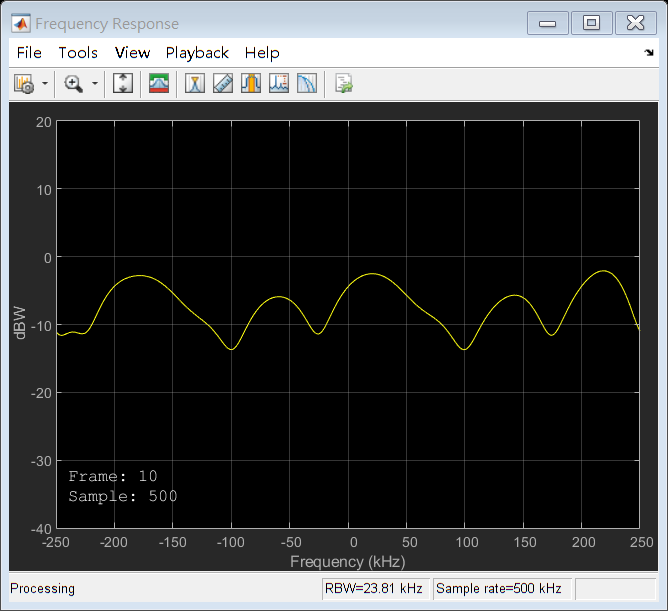

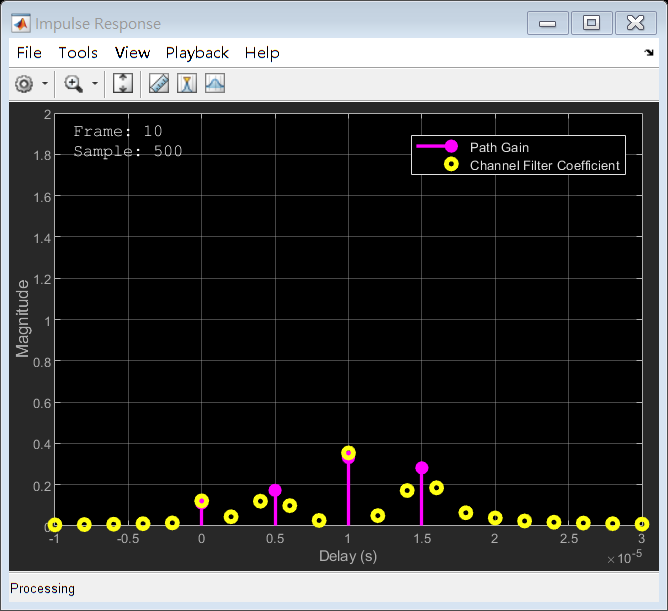

rayChan.Visualization = 'Impulse and frequency responses';
rayChan.SamplesToDisplay = '100%';

% Display impulse and frequency responses for 2 frames
numFrames = 10;
for i = 1:numFrames 
    % Create random data
    msg = randi([0 1],bitsPerFrame,1); 
    % Modulate data
    modSignal = qpskMod(msg); 
    % Filter data through channel and show channel responses
    rayChan(modSignal);
end

As you can see, the channel frequency response is not flat and may have deep fades over the 500K Hz bandwidth. Because the power level varies over the bandwidth of the signal, it is referred to as frequency-selective fading.

## Doppler Spectrum

For the same channel specification, we now display the Doppler spectrum for its first discrete path, which is a statistical characterization of the fading process. The System object makes periodic measurements of the Doppler spectrum (blue stars). Over time with more samples processed by the System object, the average of this measurement better approximates the theoretical Doppler spectrum (yellow curve).

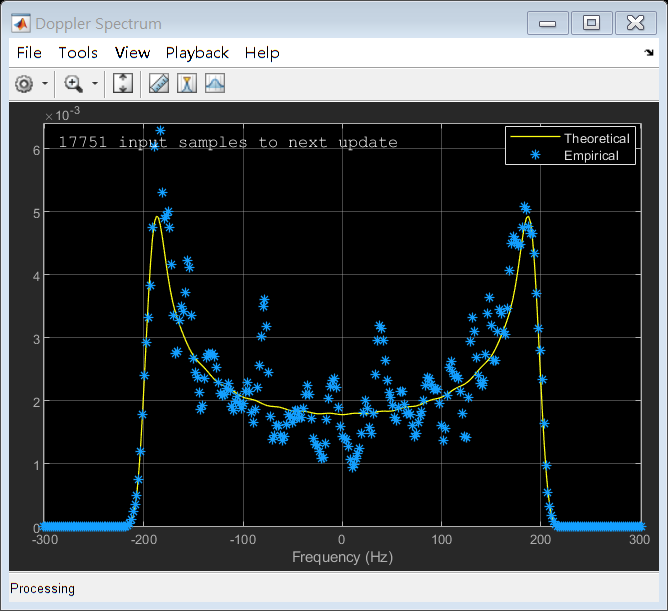

release(rayChan);
rayChan.Visualization = 'Doppler spectrum';

% Display Doppler spectrum from 5000 frame transmission
numFrames = 5000;
for i = 1:numFrames 
    msg = randi([0 1],bitsPerFrame,1); 
    modSignal = qpskMod(msg); 
    rayChan(modSignal);
end

## Channel Variations in the Time-Dalay Domain

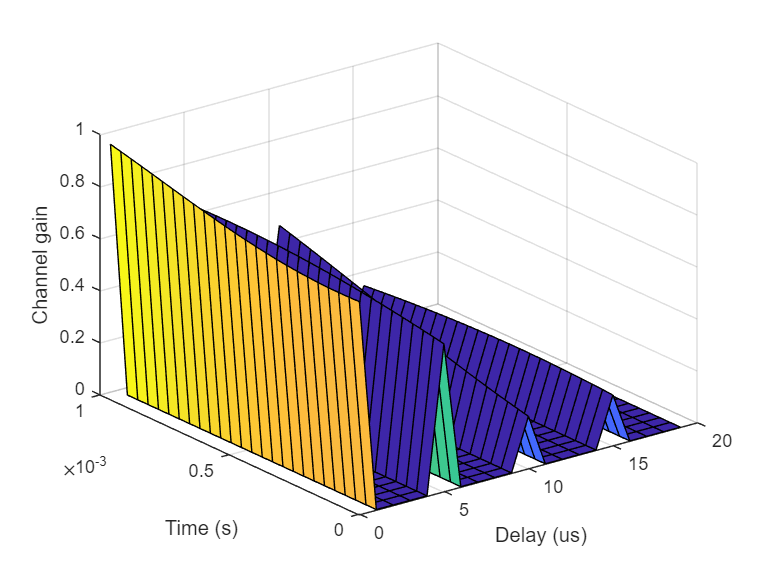

release(rayChan);
rayChan.Visualization = 'Off'; % Turn off Rayliegh object visualization 

msg = randi([0 1],bitsPerFrame,1); 
modSignal = qpskMod(msg); 
[~,rayPathGain] = rayChan(modSignal);

% Create time-delay channel
SampleNum = length(rayPathGain);
SampleInv = 20;     % Sample interval for showing in figure
MaxDelay = 20;      % Maximun delay is set to 20 us
DelayPathgain = zeros(SampleNum/SampleInv,MaxDelay);   
DelayPathgain(:,1:5:20) = rayPathGain(1:SampleInv:SampleNum,:);

%figure(1)
surf(0:MaxDelay-1, (0:SampleNum/SampleInv-1)*SampleInv/rayChan.SampleRate, ...
     abs(DelayPathgain)); % rayChan.SampleRate
% colorbar
xlabel('Delay (us)');
ylabel('Time (s)');
zlabel('Channel gain');

## Narrowband or Frequency-Flat Fading

When the bandwidth is too small for the signal to resolve the individual components, the frequency response is approximately flat because of the minimal time dispersion caused by the multipath channel. This kind of multipath fading is often referred to as narrowband fading, or frequency-flat fading.

We now reduce the signal bandwidth from 500 ksym/s to 20 ksym/s, so the delay span (15 microseconds) of the channel is much smaller than the QPSK symbol period (50 microseconds). The resultant impulse response has very small intersymbol interference (ISI) and the frequency response is approximately flat.

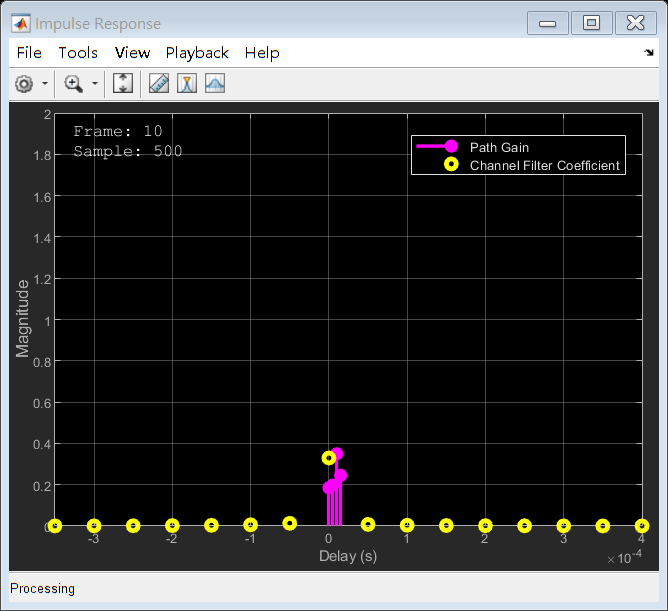

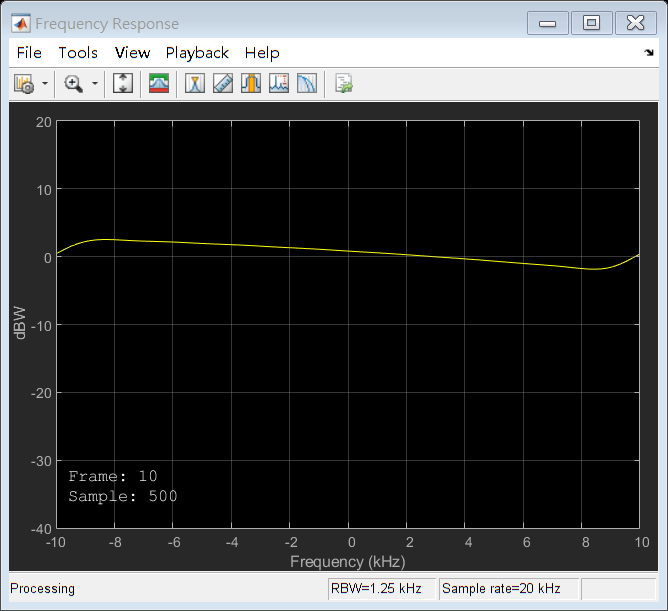

release(rayChan);  
rayChan.Visualization = 'Impulse and frequency responses';
rayChan.SampleRate = sampleRate20kHz; 
rayChan.SamplesToDisplay = '100%';  % Display one of every four samples

% Display impulse and frequency responses for 2 frames
numFrames = 10;
for i = 1:numFrames 
    msg = randi([0 1],bitsPerFrame,1);  
    modSignal = qpskMod(msg); 
    rayChan(modSignal); 
end

## Channel Variations in the Time-Dalay Domain

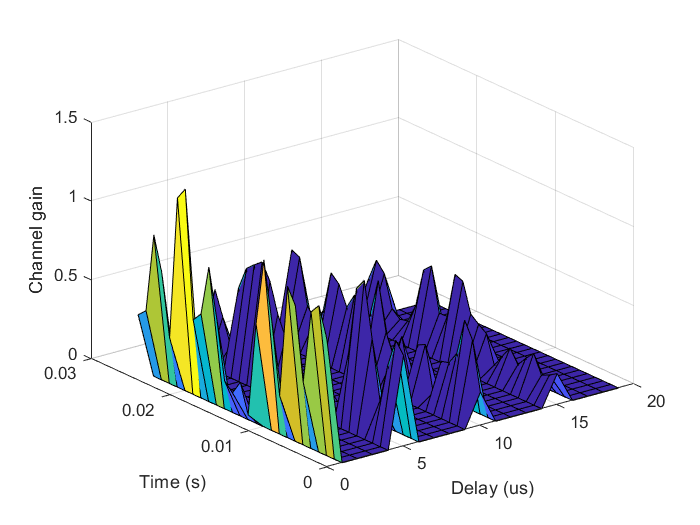

release(rayChan);
rayChan.Visualization = 'Off'; % Turn off Rayliegh object visualization 

msg = randi([0 1],bitsPerFrame,1); 
modSignal = qpskMod(msg); 
[~,rayPathGain] = rayChan(modSignal);

% Create time-delay channel
SampleNum = length(rayPathGain);
SampleInv = 20;     % Sample interval for showing in figure
MaxDelay = 20;      % Maximun delay is set to 20 us
DelayPathgain = zeros(SampleNum/SampleInv,MaxDelay);   
DelayPathgain(:,1:5:20) = rayPathGain(1:SampleInv:SampleNum,:);

%figure(1)
surf(0:MaxDelay-1, (0:SampleNum/SampleInv-1)*SampleInv/rayChan.SampleRate, ...
     abs(DelayPathgain)); % rayChan.SampleRate
% colorbar
xlabel('Delay (us)');
ylabel('Time (s)');
zlabel('Channel gain');

## Model Narrowband Fading Channels as a Single-Path Fading Channel

To simplify and speed up modeling, narrowband fading channels are typically modeled as a single-path fading channel. That is, a multipath fading model overspecifies a narrowband fading channel. The following settings correspond to a narrowband fading channel. Notice that the shape of the bandlimited impulse response is flat.

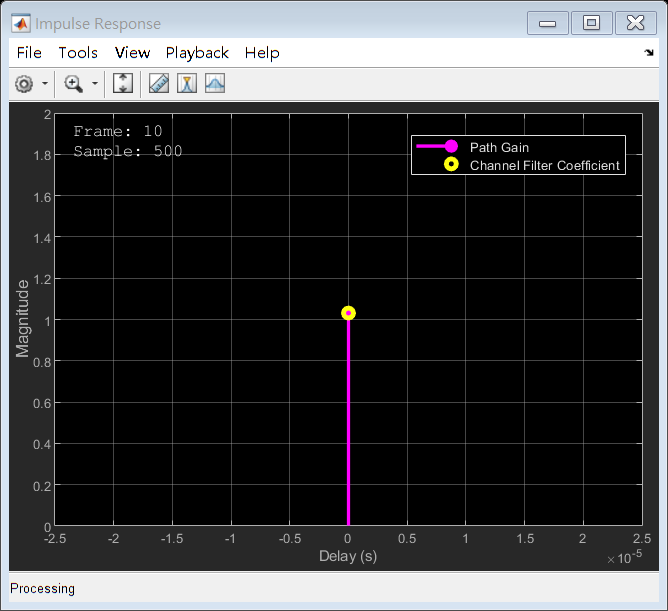

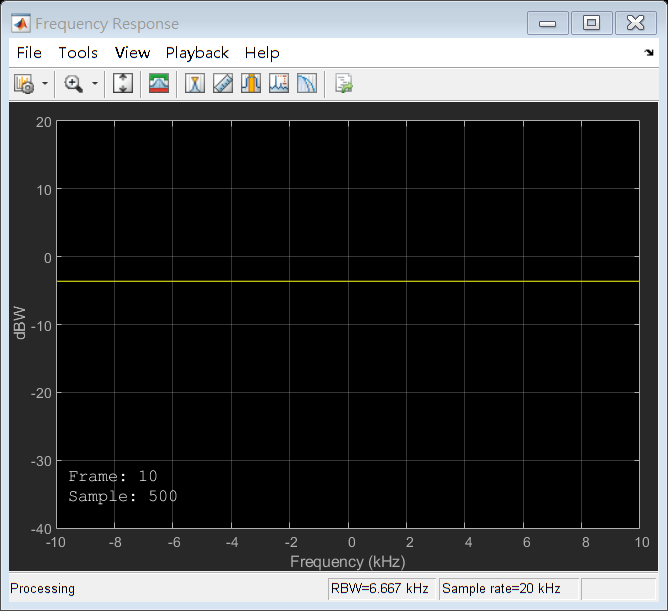

release(rayChan);  
rayChan.PathDelays = 0;        % Single fading path with zero delay
rayChan.AveragePathGains = 0;  % Average path gain of 1 (0 dB)

for i = 1:numFrames % Display impulse and frequency responses for 2 frames
    msg = randi([0 1],bitsPerFrame,1); 
    modSignal = qpskMod(msg); 
    rayChan(modSignal); 
end

We make use of a [`timescope`](docid:dsp_ref#mw_a35c8917-4fd1-4557-b840-f27aeb1567be) object to view their path gains over time. Note that the magnitude fluctuates over approximately a 30-40 dB  range for the Rayleigh fading channel (yellow curve).

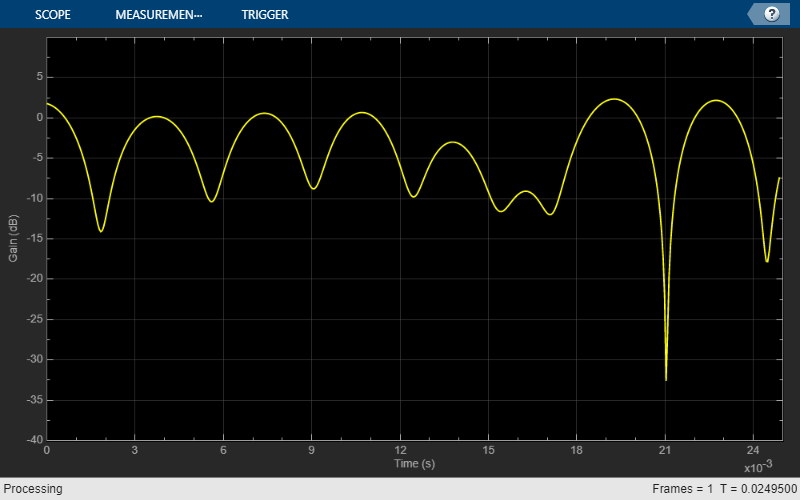

release(rayChan);
rayChan.Visualization = 'Off'; % Turn off Rayliegh object visualization 

% Configure a Time Scope System object to show path gain magnitude
gainScope = timescope( ...
    'SampleRate',rayChan.SampleRate, ...
    'TimeSpanSource','Property',...
    'TimeSpan',bitsPerFrame/2/rayChan.SampleRate, ... % One frame span
    'Name','Multipath Gain', ...
    'ShowGrid',true, ...
    'YLimits',[-40 10], ...
    'YLabel','Gain (dB)');

% Compare the path gain outputs from Rayliegh object for one frame
msg = randi([0 1],bitsPerFrame,1);
modSignal = qpskMod(msg);
[~,rayPathGain] = rayChan(modSignal);

% Form the path gains as a one-channel input to the time scope
gainScope(10*log10(abs(rayPathGain).^2));

## Fading Channel Impact on Signal Constellation

We now return to our original four-path Rayleigh fading channel. We use a [`ConstellationDiagram`](docid:comm_ref#btqw_93-1) System object to show the impact of narrowband fading on the signal constellation. To slow down the channel dynamics for visualization purposes, we reduce the maximum Doppler shift to 5 Hz. Compared with the QPSK channel input signal, you can observe signal attenuation and rotation at the channel output, as well as some signal distortion due to the small amount of ISI in the received signal.

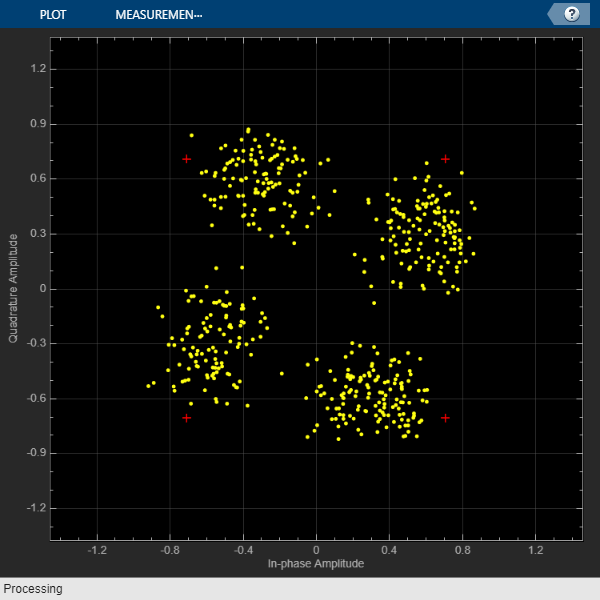

release(rayChan);

rayChan.PathDelays = delayVector;
rayChan.AveragePathGains = gainVector;
rayChan.MaximumDopplerShift = 5;

% Configure a Constellation Diagram System object to show received signal
constDiag = comm.ConstellationDiagram( ...
    'Name','Received Signal After Rayleigh Fading');

numFrames = 16;

for n = 1:numFrames 
    msg = randi([0 1],bitsPerFrame,1); 
    modSignal = qpskMod(msg); 
    rayChanOut = rayChan(modSignal); 
    % Display constellation diagram for Rayleigh channel output
    constDiag(rayChanOut);
end

When we increase the signal bandwidth to 500 ksym/s, we see much greater distortion in the signal constellation. This distortion is the ISI that comes from time dispersion of the wideband signal. The delay span (15 microseconds) of the channel is now larger than the QPSK symbol period (4 microseconds), so the resultant bandlimited impulse response is no longer approximately flat.

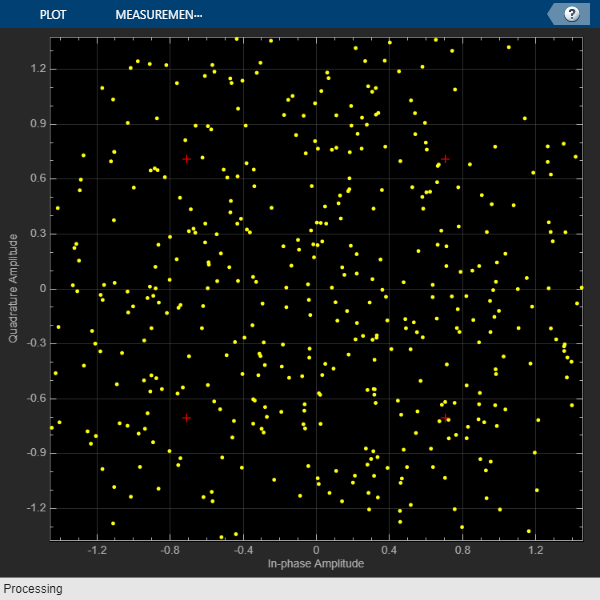

release(rayChan);
release(constDiag);
rayChan.SampleRate = sampleRate500kHz; 

for n = 1:numFrames
    msg = randi([0 1],bitsPerFrame,1); 
    modSignal = qpskMod(msg); 
    rayChanOut = rayChan(modSignal); 
    constDiag(rayChanOut);
end